# 2021-01-21-Zuwan-in-vivo-test

## Input

base_path = fullfile('H:/2021-01-21-Zuwan-in-vivo-test/control/');
img_files = dir(strcat(base_path, '*.tif'));

imgs = cell(4, 1);
            
for r=1:4
    tic
    fprintf('Loading image #%d...', r);

    current_path = strcat(img_files(r).folder, '/', img_files(r).name);
    current_img = new_LoadMultipageTiff(current_path, 'uint8', 'uint8', false);

    imgs{r} = current_img;
    fprintf(sprintf('[time = %.2f s]\n', toc));
end

## Process

processing image #1...

stats_dots = 9869×3 int16 matrix
    274   1462      1
    275   1237      1
    288   1050      2
    317   1038      1
    395    905      1
    530   1701      2
    547   1738      2
    573    925      1
    574    703      1
    588   1045      1


n_dots = 9869

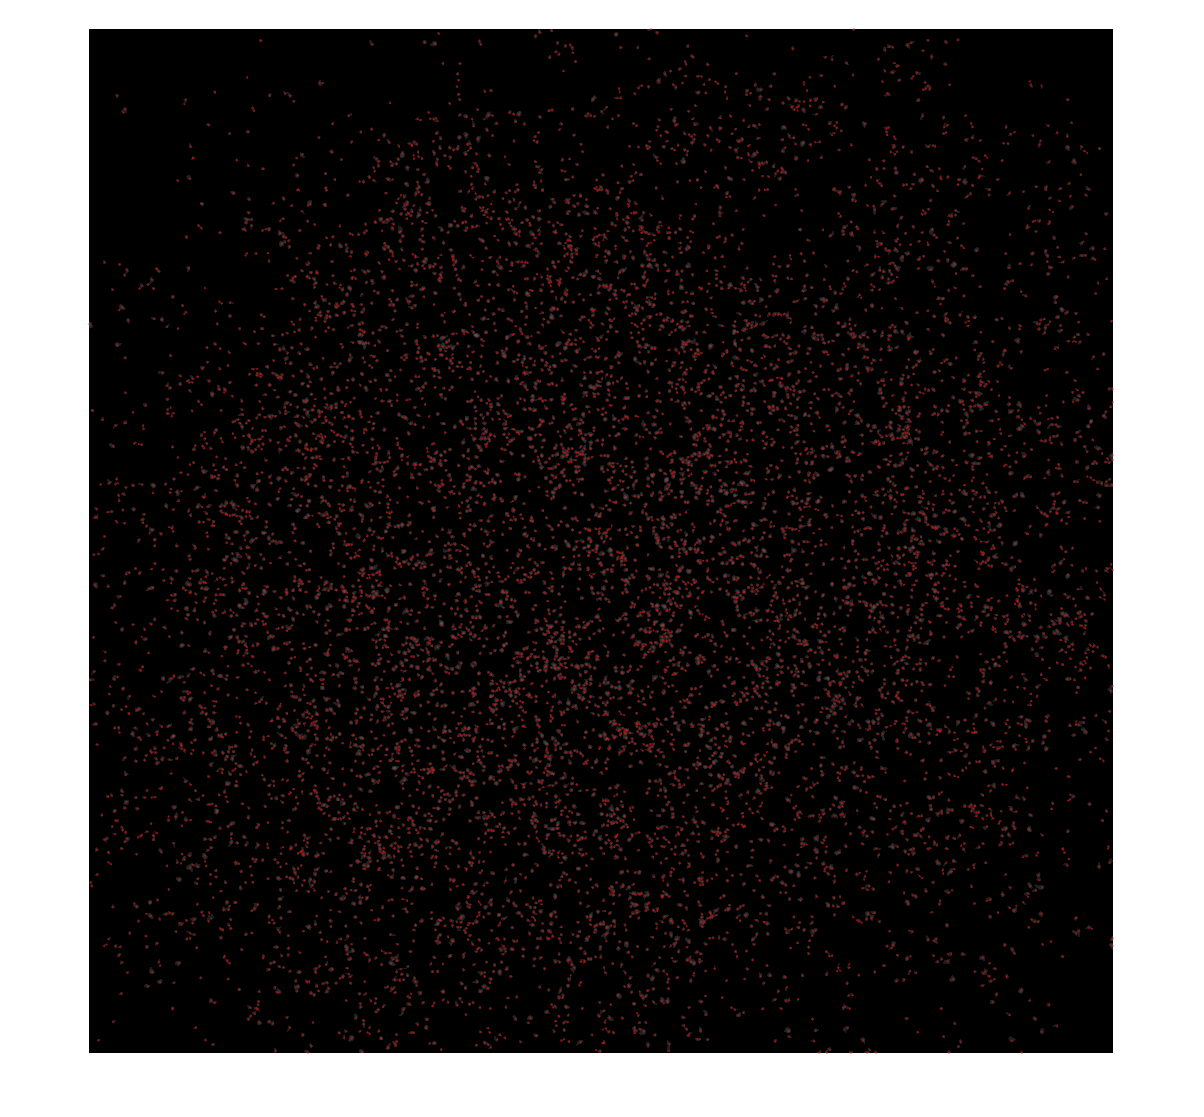

[time = 228.67 s]


processing image #2...

stats_dots = 3291×3 int16 matrix
     28    750      1
    241   1029      1
    470   1559      1
    525   1771      1
    538   1069      1
    640    640      1
    845   1135      1
    853   1151      1
    869   1068      1
    963   1019      1


n_dots = 3291

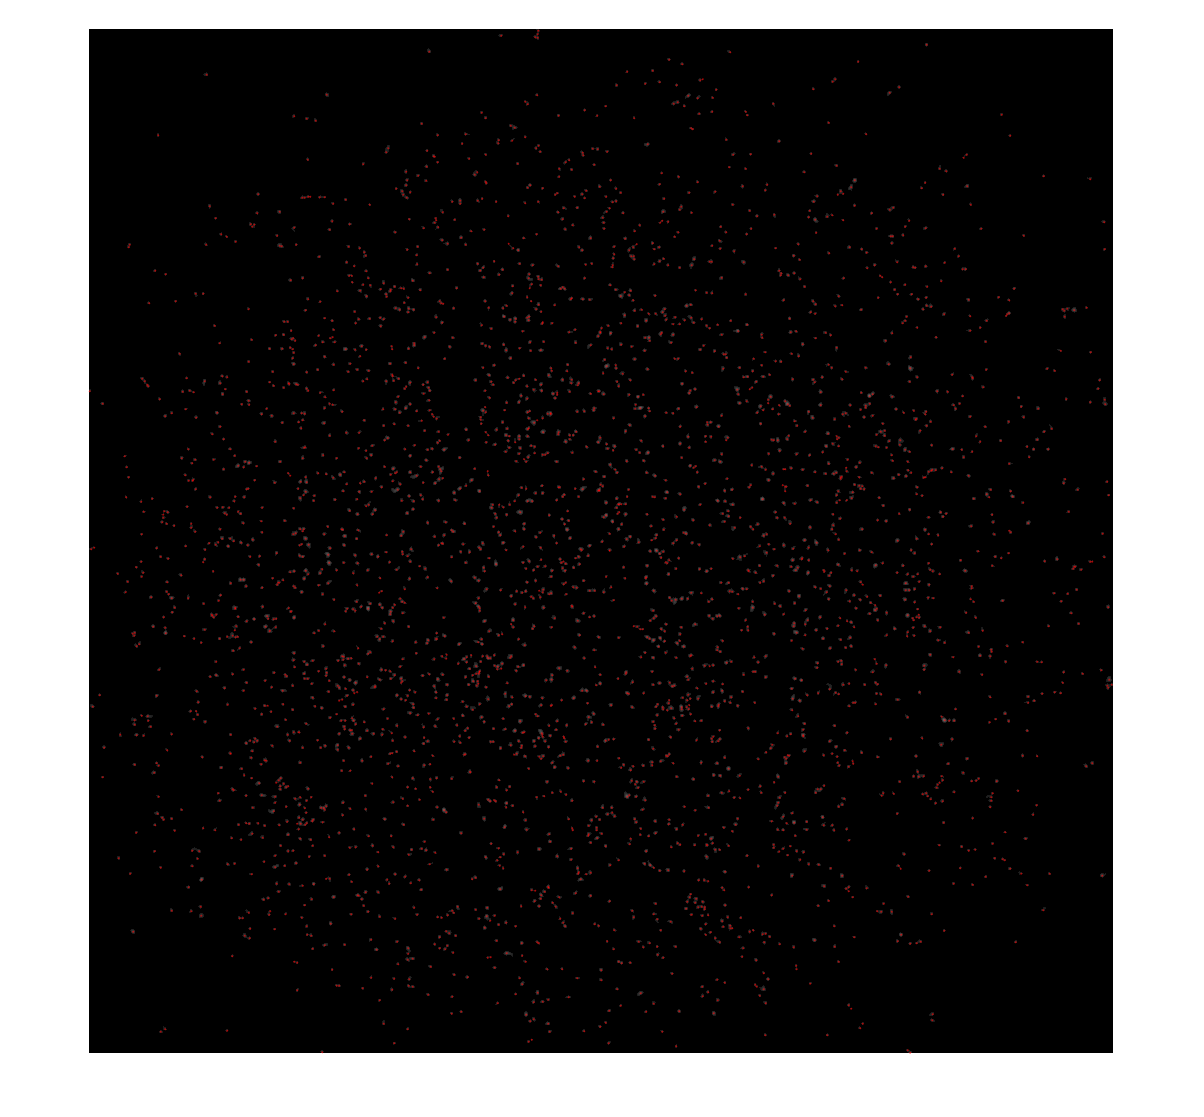

[time = 218.16 s]


processing image #3...

stats_dots = 3432×3 int16 matrix
     63   1235      2
    102    410      1
    234     51      3
    327    492      1
    332   1059      1
    351    781      1
    408    664      1
    469    618      1
    475   1775      1
    480   1766      1


n_dots = 3432

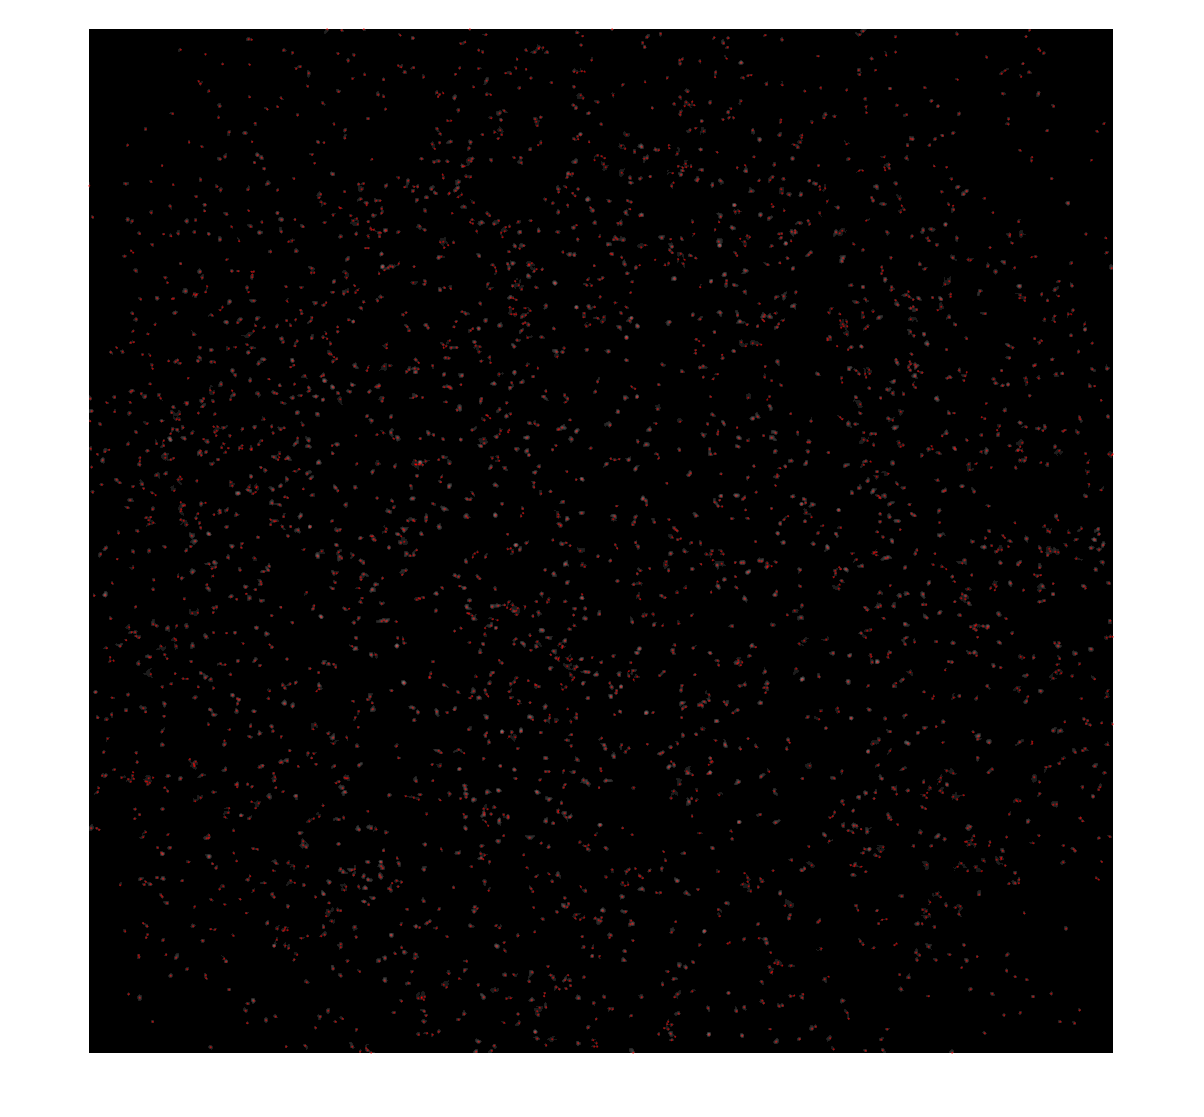

[time = 213.41 s]


processing image #4...

stats_dots = 965×3 int16 matrix
    401    826      1
    594   1006      1
    665    518      1
   1395   1554      1
   1402    616      2
   1562   1607      2
   1256   1604      4
    577   1905      5
    820   1937      6
   1162   1232      5


n_dots = 965

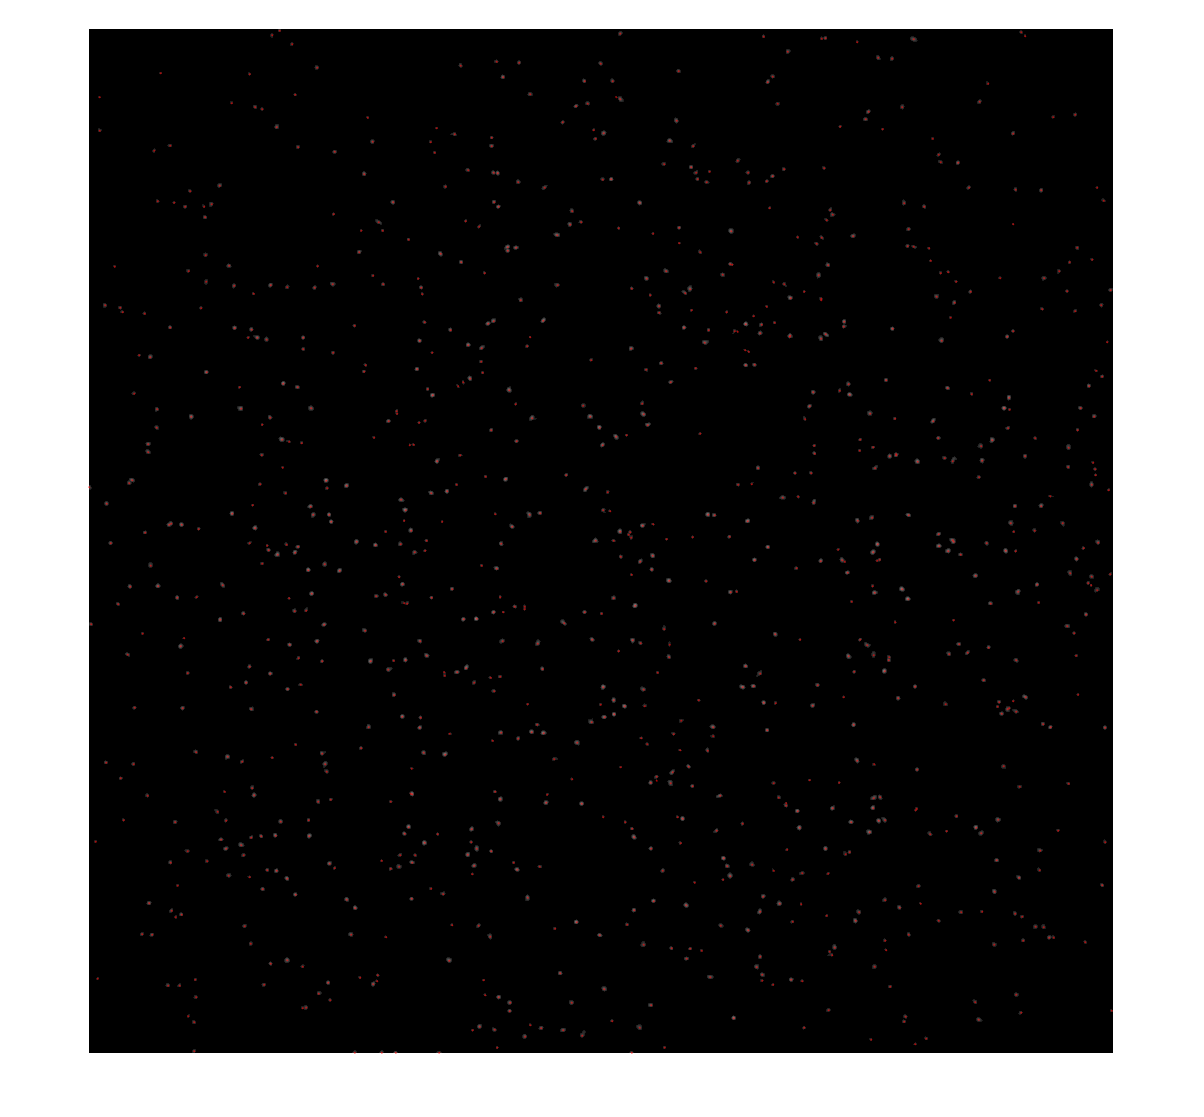

[time = 218.39 s]


volume_threshold = [100 800];
denoised_imgs = cell(4, 1);

allSpots = [];
allReads = [];
genes = {"Snap25", "Plp1", "Gfap", 'C1qa'}; 

for r=1:4
    tic
    fprintf('processing image #%d...', r);
    
    current_img =  imgs{r};
    
    % gaussian filter
    blur_img = imgaussfilt3(current_img, 2);
    % thresholding 
    bw_img = blur_img > 25; 
    stats = regionprops3(bw_img, 'Volume', "VoxelIdxList");
    outlier = (stats.Volume < volume_threshold(1)) | (stats.Volume > volume_threshold(2));
    outlier = stats(outlier,:);
    outlier = cell2mat(outlier.VoxelIdxList);
    bw_img(outlier) = 0;
    blur_img = blur_img .* uint8(bw_img);
    
    bw_dots = imregionalmax(blur_img);
    stats_dots = regionprops3(bw_dots, "Centroid");
    stats_dots = int16(stats_dots.Centroid)
    n_dots = size(stats_dots, 1)
    
    allSpots = [allSpots; stats_dots];
    allReads = [allReads; repmat(genes{r}, n_dots, 1)];
    
    fname = fullfile(base_path, 'output', sprintf('pp_img_%d.tif', r));
    if exist(fname, 'file') == 2
        delete(fname);
    end
    for j=1:size(blur_img, 3)     
        imwrite(blur_img(:,:,j), fname, 'writemode', 'append');        
    end

    plot_centroids(stats_dots, max(blur_img, [], 3), 2, 'r')
    fprintf(sprintf('[time = %.2f s]\n', toc));
end

save(fullfile(base_path, 'output', 'allSpots.mat'), 'allSpots', 'allReads');c

fname = fullfile(base_path, 'output', 'blur_img.tif');
if exist(fname, 'file') == 2
    delete(fname);
end
for j=1:size(blur_img, 3)     
    imwrite(blur_img(:,:,j), fname, 'writemode', 'append');        
end